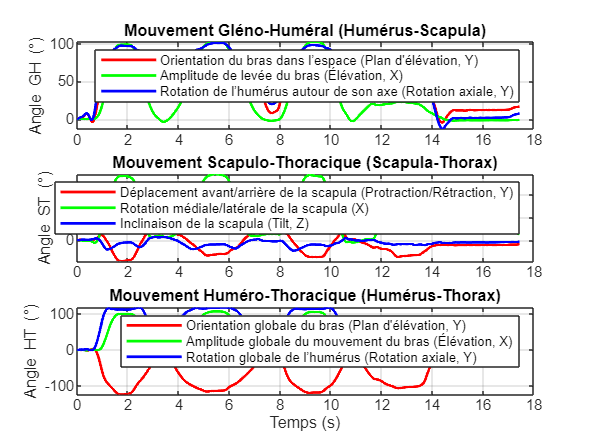

%% ================= Traitement cinématique ================= %%       
clear; clc; close all;

%% -------- Chargement de l'environnement -------- %%
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\3D Kinematics and Inverse Dynamics'));

%% -------- Sélection du mouvement  -------- %%
choice = 3; % Modifier pour changer de mouvement

Subjects = {'JV18'}; 
subj_idx = 1; % Vérifie que subj_idx est bien défini
% 'MF01', 'TF02', 'YL03','SC04', 'RF05', 'AP06'
% 'TD07', 'IS08', 'LC09', 'MP10', 'PK11'
% 'TF12','JM13', 'GD14', 'LD15', 'LM16','NQ17', 'JV18'
% 'EG19', 'MG20', 'LB21', 'AP22', 'SC23'
% 'TM24', 'EG25', 'RL26'

% Définition du fichier
file_names = {... 
    % 'MF01-MF01-20240101-PROTOCOL01-ANALYTIC1-.c3d', ... % Élévation sagittale
    % 'MF01-MF01-20240101-PROTOCOL01-ANALYTIC2-.c3d', ... % Élévation frontale
    % 'MF01-MF01-20240101-PROTOCOL01-ANALYTIC3-.c3d', ... % Rotation externe
    % 'MF01-MF01-20240101-PROTOCOL01-ANALYTIC4-.c3d'};    % Rotation interne

    sprintf('%s-%s-20240101-PROTOCOL01-FUNCTIONAL1-.c3d', Subjects{subj_idx}, Subjects{subj_idx}), ...
    sprintf('%s-%s-20240101-PROTOCOL01-FUNCTIONAL2-.c3d', Subjects{subj_idx}, Subjects{subj_idx}), ...
    sprintf('%s-%s-20240101-PROTOCOL01-FUNCTIONAL3-.c3d', Subjects{subj_idx}, Subjects{subj_idx}), ...
    sprintf('%s-%s-20240101-PROTOCOL01-FUNCTIONAL4-.c3d', Subjects{subj_idx}, Subjects{subj_idx}) ...
};

chemin_dossier = sprintf('C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s', Subjects{subj_idx});
fichier = fullfile(chemin_dossier, file_names{choice});

% Lecture du fichier C3D
c3dH = btkReadAcquisition(fichier);


%% -------- Extraction des marqueurs -------- %%
markers = btkGetMarkers(c3dH);
nFrames = btkGetLastFrame(c3dH);
fs = 200;
time = (0:nFrames-1) / fs;

%% -------- Initialisation des matrices pour stocker les angles -------- %%
Angles_GH = zeros(nFrames, 3);
Angles_ST = zeros(nFrames, 3);
Angles_HT = zeros(nFrames, 3);
normalize_vector = @(v) v / norm(v);

%% ======== Extraction des angles d'Euler selon Wu et al. 2005 ======== %%
for i = 1:nFrames

    % Etape 1 : Définition des repères segmentaires %

    % Repère du thorax
    SJN = markers.SJN(i,:); CV7 = markers.CV7(i,:);
    TV8 = markers.TV8(i,:); SXS = markers.SXS(i,:);
    Ot = SJN;
    Yt = normalize_vector(mean([SXS; TV8]) - mean([SJN; CV7]));
    Zt = normalize_vector(cross(SJN - CV7, mean([SXS; TV8]) - SJN));
    Xt = normalize_vector(cross(Yt, Zt));
    
    % Repère de la scapula
    RSAA = markers.RSAA(i,:); RSRS = markers.RSRS(i,:); RSIA = markers.RSIA(i,:);
    Os = RSAA;
    Zs = normalize_vector(RSAA - RSRS);
    Xs = normalize_vector(cross(RSIA - RSAA, RSRS - RSAA));
    Ys = normalize_vector(cross(Xs, Zs));
    
    % Repère de l'humérus
    RGH = markers.RSCT(i,:); RHME = markers.RHME(i,:); RHLE = markers.RHLE(i,:);
    Rmid_HLE_HME = mean([RHLE; RHME]);
    Oh = RGH;
    Yh = normalize_vector(RGH - Rmid_HLE_HME);
    Xh = normalize_vector(cross(RGH - RHLE, RGH - RHME));
    Zh = normalize_vector(cross(Yh, Xh));

    % Etape 2 : Calcul des matrices de rotation %

    % Matrices de rotation par rapport au repère global
    Rt = [Xt', Yt', Zt'];
    Rs = [Xs', Ys', Zs'];
    Rh = [Xh', Yh', Zh'];
    
    % Correction orthonormalité (A^T=A = I)
    % Utilisation de "svd" pour garantir que les matrices R sont orthogonales
    [Ut,~,Vt] = svd(Rt); Rt = Ut * Vt';
    [Us,~,Vs] = svd(Rs); Rs = Us * Vs';
    [Uh,~,Vh] = svd(Rh); Rh = Uh * Vh';

    % Matrices de rotation relatives
    R_HT = Rt' * Rh;  % Humérus par rapport au thorax
    R_ST = Rt' * Rs;  % Scapula par rapport au thorax
    R_GH = Rs' * Rh;  % Humérus par rapport à la scapula

    % Etape 3 : Extraction des angles d'Euler selon une séquence spécifique pour chaque angle 

    Angles_HT(i,:) = squeeze(R2mobileYXY_array3(reshape(R_HT,3,3,1))); % Huméro-Thoracique
    Angles_ST(i,:) = squeeze(R2mobileYXZ_array3(reshape(R_ST,3,3,1))); % Scapulo-Thoracique
    Angles_GH(i,:) = squeeze(R2mobileYXY_array3(reshape(R_GH,3,3,1))); % Gléno-Huméral
end

%% -------- Filtrage et correction des discontinuités -------- %%

% Utilisation de la fonction "unwrap" pour limiter les sauts de cardan liés aux angles de Euler 
Angles_GH = unwrap(Angles_GH);
Angles_ST = unwrap(Angles_ST);
Angles_HT = unwrap(Angles_HT);

% Filtrage passe-bas pour limiter les variations des données des marqueurs et de potentiels données 
fc = 6;
[b, a] = butter(2, fc / (fs/2), 'low');
Angles_GH = filtfilt(b, a, Angles_GH);
Angles_ST = filtfilt(b, a, Angles_ST);
Angles_HT = filtfilt(b, a, Angles_HT);

% Recentrage des angles pour éliminer un biais initial (ex : commencer à -200°) et recentrer les courbes
Angles_GH(:,3) = Angles_GH(:,3) - mean(Angles_GH(1:10,3));
Angles_ST(:,3) = Angles_ST(:,3) - mean(Angles_ST(1:10,3));
Angles_HT(:,3) = Angles_HT(:,3) - mean(Angles_HT(1:10,3));

Angles_GH(:,2) = Angles_GH(:,2) - mean(Angles_GH(1:10,2));
Angles_ST(:,2) = Angles_ST(:,2) - mean(Angles_ST(1:10,2));
Angles_HT(:,2) = Angles_HT(:,2) - mean(Angles_HT(1:10,2));

Angles_GH(:,1) = Angles_GH(:,1) - mean(Angles_GH(1:10,1));
Angles_ST(:,1) = Angles_ST(:,1) - mean(Angles_ST(1:10,1));
Angles_HT(:,1) = Angles_HT(:,1) - mean(Angles_HT(1:10,1));

%% -------- Affichage des angles -------- %%
figure;

% Mouvement Gléno-Huméral (GH) - Rotation de l'humérus par rapport à la scapula
subplot(3,1,1);
plot(time, rad2deg(Angles_GH(:,1)), 'r', 'LineWidth', 1.5); hold on;
plot(time, rad2deg(Angles_GH(:,2)), 'g', 'LineWidth', 1.5);
plot(time, rad2deg(Angles_GH(:,3)), 'b', 'LineWidth', 1.5); hold off;
ylabel('Angle GH (\circ)');
legend('Orientation du bras dans l’espace (Plan d''élévation, Y)', ...
       'Amplitude de levée du bras (Élévation, X)', ...
       'Rotation de l’humérus autour de son axe (Rotation axiale, Y)');
title('Mouvement Gléno-Huméral (Humérus-Scapula)');
grid on;

% Mouvement Scapulo-Thoracique (ST) - Déplacement de la scapula sur le thorax
subplot(3,1,2);
plot(time, rad2deg(Angles_ST(:,1)), 'r', 'LineWidth', 1.5); hold on;
plot(time, rad2deg(Angles_ST(:,2)), 'g', 'LineWidth', 1.5);
plot(time, rad2deg(Angles_ST(:,3)), 'b', 'LineWidth', 1.5); hold off;
ylabel('Angle ST (\circ)');
legend('Déplacement avant/arrière de la scapula (Protraction/Rétraction, Y)', ...
       'Rotation médiale/latérale de la scapula (X)', ...
       'Inclinaison de la scapula (Tilt, Z)');
title('Mouvement Scapulo-Thoracique (Scapula-Thorax)');
grid on;

% Mouvement Huméro-Thoracique (HT) - Mouvement global de l'humérus par rapport au thorax
subplot(3,1,3);
plot(time, rad2deg(Angles_HT(:,1)), 'r', 'LineWidth', 1.5); hold on;
plot(time, rad2deg(Angles_HT(:,2)), 'g', 'LineWidth', 1.5);
plot(time, rad2deg(Angles_HT(:,3)), 'b', 'LineWidth', 1.5); hold off;
ylabel('Angle HT (\circ)');
legend('Orientation globale du bras (Plan d''élévation, Y)', ...
       'Amplitude globale du mouvement du bras (Élévation, X)', ...
       'Rotation globale de l’humérus (Rotation axiale, Y)');
title('Mouvement Huméro-Thoracique (Humérus-Thorax)');
xlabel('Temps (s)');
grid on;